For this particular assignment, since the robotic arm and the obstacles are assumed to be a collection of triangles, any form of real world collision is simplified to the fact of intersection between the triangles of the robotic arm and the obstacle.

One of the many approaches towards understanding this concept is to consider all the 6 edges(3 for each triangle)and whether they act as separating lines where all verticesot one triangle lie on one side.

Also, the possible scenarios to check for are as follows:

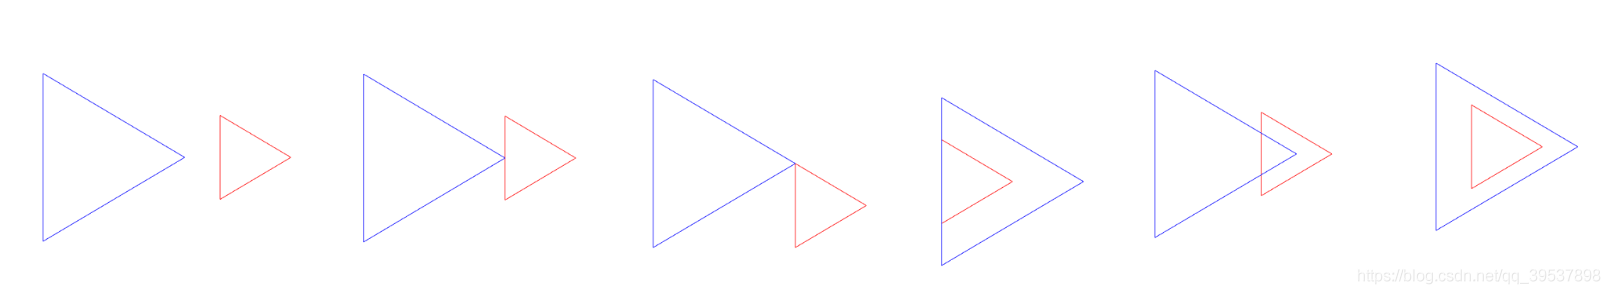

Moving from left to right, the possible scenarios include:

Non intersecting triangles

Triangles intersecting at a single point(one line-one point)

Triangles intersecting at a single point (one point-one point)

Triangles intersecting via line overlap

Triangles intersecting at multiple points

One triangle overlapping the other

FUNCTION DESCRIPTION

**For this part of the assignment you have to create the function triangle_intersection with the following input and output arguments:**

**P1, P2: a 3x2 array(each), describing the vertices of a triangle, where the first column represents x coordinates and the second column represents y coordinates.**

**flag: Return value for the function, set to true if determines intersection (including overlapping) between triangles and false otherwise.**

**Once completed, you can try out multiple scearios to check if your algorithm works for all cases as discussed above.**

x = [10*rand(),10*rand(),10*rand()]; 
y = [10*rand(),10*rand(),10*rand()];
P1 = [x;y];

x = [10*rand(),10*rand(),10*rand()]; 
y = [10*rand(),10*rand(),10*rand()];
P2 = [x;y];

% x = [0,1,-1]; 
% y = [2*sqrt(1/3),-sqrt(1/3),-sqrt(1/3)];
% P1 = [x;y];
% 
% x = [0,1,-1]; 
% y = [-2*sqrt(1/3),sqrt(1/3),sqrt(1/3)];
% P2 = [x;y];

if_intersect=[];
for i=1:3
    if i<3
        j=i+1;
    else
        j=1;
    end
    p=(P1(2,i)-P1(2,j))/(P1(1,i)-P1(1,j));
    q=(P1(2,j)*P1(1,i)-P1(2,i)*P1(1,j))/(P1(1,i)-P1(1,j));
    for z=1:3
        if z<3
            w=z+1;
        else
            w=1;
        end
        [i,j,z,w];
        
        m=(P2(2,z)-P2(2,w))/(P2(1,z)-P2(1,w));
        n=(P2(2,w)*P2(1,z)-P2(2,z)*P2(1,w))/(P2(1,z)-P2(1,w));
        [p q m n];
        intersection_x=(n-q)/(p-m);

        if  ((intersection_x<=max(P1(1,i),P1(1,j)))&(intersection_x>=min(P1(1,i),P1(1,j))))
            if_intersect=[if_intersect,1];            
        else
            if_intersect=[if_intersect,0];
        end

    end
end




flag = triangle_intersection(P1,P2);

Two triangles overlap


if flag == 1
    disp("Intersection")
else
    disp("No Intersection")
end

Intersection


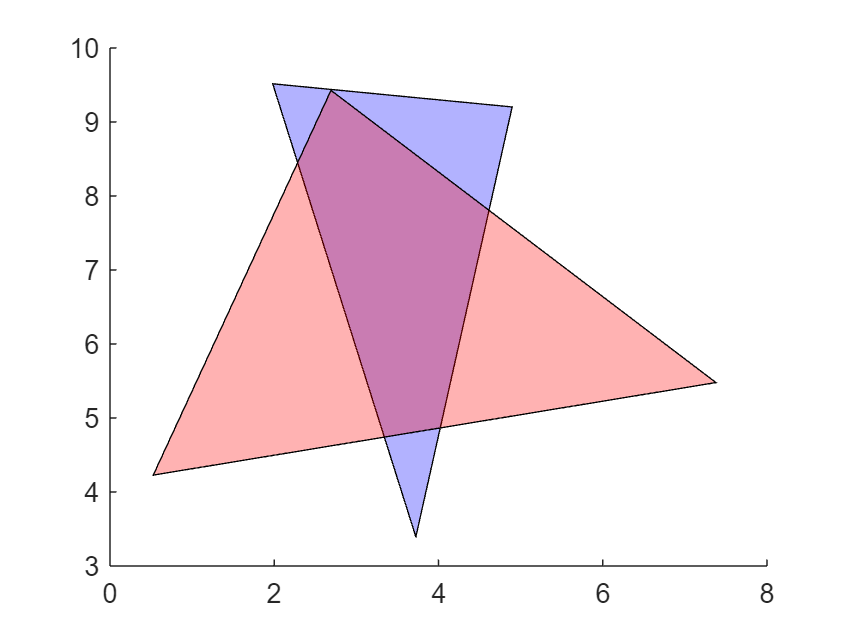


patch(P1(1,:),P1(2,:),'b','FaceAlpha',.3);
hold on 
patch(P2(1,:),P2(2,:),'r','FaceAlpha',.3);
hold off

function flag = triangle_intersection(P1, P2)
% triangle_test : returns true if the triangles overlap and false otherwise

%%% All of your code should be between the two lines of stars.
% *******************************************************************

Det_P1=[P1',ones(3,1)];
S_p1=abs(0.5*det(Det_P1));
Det_P2=[P2',ones(3,1)];
S_p2=abs(0.5*det(Det_P2));





if S_p2<=0 | S_p1 <=0
    disp("Please check the triangle coordinate data")
    flag=1;
else
    
    Area_List=[];
    for i=1:3
        Area_total=0;
        [P2(1,i),P2(2,i),1;P1(1,1),P1(2,1),1;P1(1,2),P1(2,2),1];
        Area_total=Area_total+abs(0.5*det([P2(1,i),P2(2,i),1;P1(1,1),P1(2,1),1;P1(1,2),P1(2,2),1]));
        Area_total=Area_total+abs(0.5*det([P2(1,i),P2(2,i),1;P1(1,1),P1(2,1),1;P1(1,3),P1(2,3),1]));
        Area_total=Area_total+abs(0.5*det([P2(1,i),P2(2,i),1;P1(1,2),P1(2,2),1;P1(1,3),P1(2,3),1]));
        Area_List=[Area_List,Area_total];
    end

    if ~isempty(find(round(Area_List,4)==round(S_p1,4)))
        disp("Two triangles overlap")
        flag=1;
    else
        if_intersect=[];
        for i=1:3
            if i<3
                j=i+1;
            else
                j=1;
            end
            p=(P1(2,i)-P1(2,j))/(P1(1,i)-P1(1,j));
            q=(P1(2,j)*P1(1,i)-P1(2,i)*P1(1,j))/(P1(1,i)-P1(1,j));
            for z=1:3
                if z<3
                    w=z+1;
                else
                    w=1;
                end
                [i,j,z,w];

                m=(P2(2,z)-P2(2,w))/(P2(1,z)-P2(1,w));
                n=(P2(2,w)*P2(1,z)-P2(2,z)*P2(1,w))/(P2(1,z)-P2(1,w));
                [p q m n];
                intersection_x=(n-q)/(p-m);

                if  ((intersection_x<=min(max(P1(1,i),P1(1,j)),max(P2(1,z),P2(1,w))))&(intersection_x>=max(min(P1(1,i),P1(1,j)),min(P2(1,z),P2(1,w)))))
                    if_intersect=[if_intersect,1];
                else
                    if_intersect=[if_intersect,0];
                end

            end
        end

        if sum(if_intersect)>0
            disp("Two triangles intersect")
            flag=1;
        else
            disp("Two triangles do not overlap")
            flag=0;
        end
    end
end







end